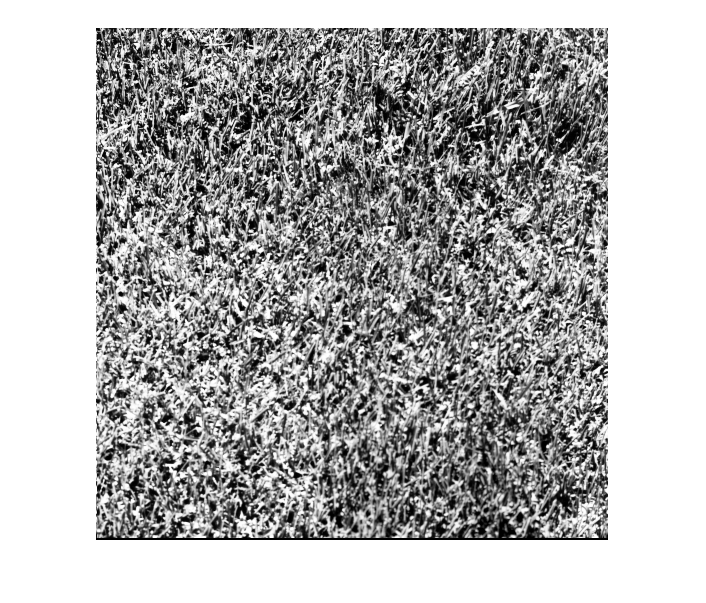

img = imread("../image_set_2/1.2.01.tiff");
img = im2gray(img);
imshow(img);

DLMI = double(img(:)); % Double Linear Matrix Image

% Contrast
alpha = 0.25;
feat = std(DLMI)/(kurtosis(DLMI)^alpha);
feat

feat = 63.8782

x = double(img(:));
% Fourth moment
M4=mean((x-mean(x)).^4);  

%variance
delta2=var(x,1); 

% Kurtosis
alfa4=M4/(delta2^2);
% Standard deviation
delta=std(x,1);  

% Contrast
Fcon=delta/(alfa4^(1/4))

Fcon = 63.8780

feat = getTamuraFeatures("../image_set_2/1.2.01.tiff");

["Hi" string(feat)]

ans = 1×7 string array
    "Hi"    "4721.4457"    "18.508458"    "13.476197"    "0.03644037"    "0.98002419"    "4734.9219"
